clear all, clc, close all;

fid = fopen('../MPC/data/stochastic/results7.json');
raw = fread(fid); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

aTc = val.states.v1;
IPTG = val.states.v2;

sbioloadproject Genetic_Toggle_Switch.sbproj

for i = 1:length(IPTG)
    trigger = strcat('time >= ', int2str((i-1)));
    evnt_IPTG = strcat('IPTG = ', num2str(IPTG(i)), '*u0');
    evnt_aTc = strcat('aTc = ', num2str(aTc(i)), '*u0');
    addevent(m1, trigger, {evnt_aTc, evnt_IPTG});
end

sim = sbiosimulate(m1);

avg_time = (0:1:1200)

avg_time =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


LacI = sim.Data(:,3);
TetR = sim.Data(:,5);

[avg_LacI, avg_TetR] = compute_average_trajectory(LacI, TetR, avg_time)

avg_LacI =   650.3805  650.7221  651.0615  651.3988  651.7340  652.0670  652.3979  652.7267  653.0533  653.3779  653.7003  654.0207  654.3389  654.6551  654.9692  655.2812  655.5912  655.8991  656.2049  656.5087  656.8104  657.1100  657.4077  657.7033  657.9969  658.2884  658.5780  658.8655  659.1510  659.4346  659.7161  659.9957  660.2732  660.5488  660.8225  661.0941  661.3638  661.6315  661.8973  662.1612  662.4231  662.6831  662.9411  663.1972  663.4514  663.7037  663.9541  664.2026  664.4492  664.6939


avg_TetR =   361.6301  361.2362  360.8454  360.4576  360.0730  359.6914  359.3128  358.9373  358.5648  358.1953  357.8289  357.4654  357.1049  356.7474  356.3929  356.0413  355.6927  355.3470  355.0043  354.6644  354.3275  353.9935  353.6624  353.3341  353.0087  352.6862  352.3665  352.0497  351.7357  351.4245  351.1161  350.8105  350.5077  350.2077  349.9105  349.6160  349.3242  349.0353  348.7490  348.4654  348.1846  347.9065  347.6310  347.3583  347.0882  346.8207  346.5559  346.2938  346.0343  345.7774


LacI_ref = 750;
TetR_ref = 300;

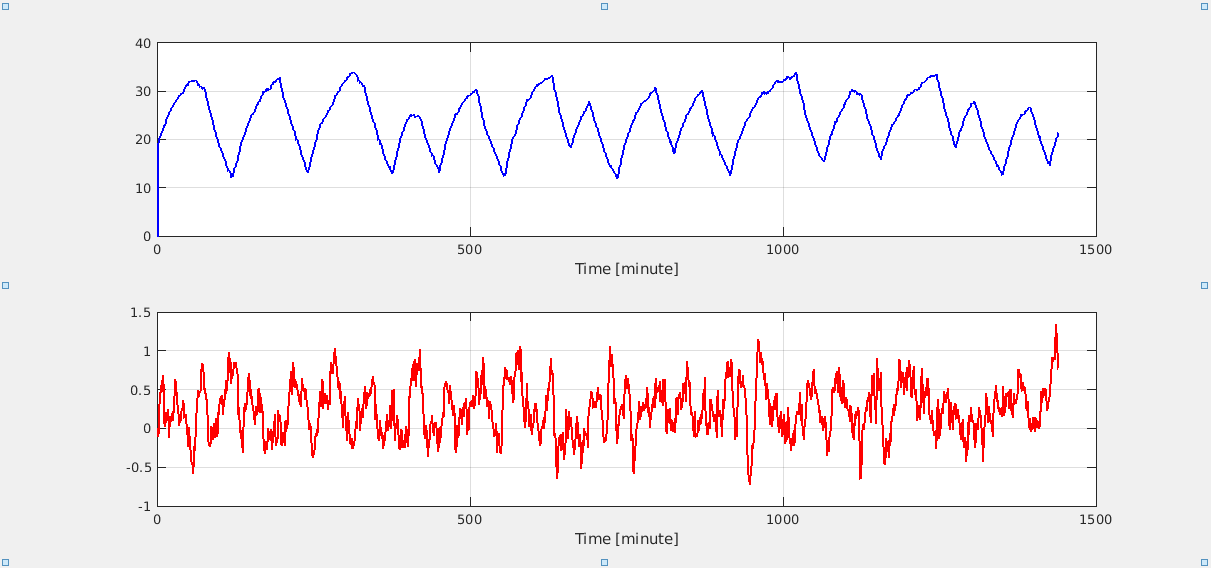

close all;
figure(1);
clf reset
plotbrowser('on');
title('Inputs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,6), 'DisplayName','aTc');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,1), 'DisplayName','IPTG');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

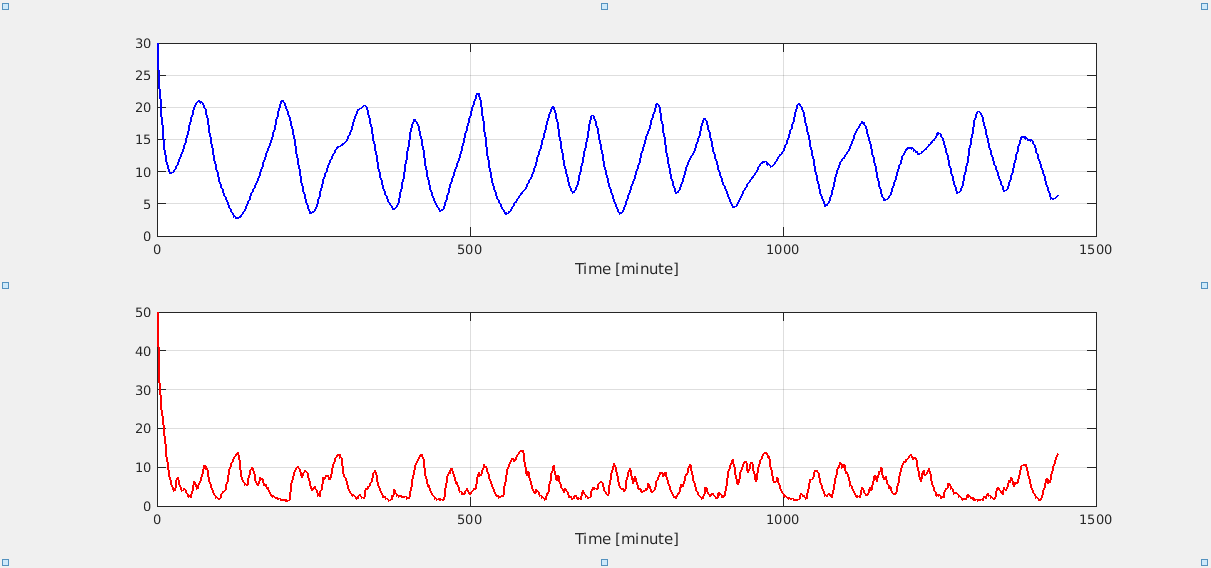

figure(2);
clf reset
plotbrowser('on');
title('mRNAs');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,2), 'DisplayName','mRNA LacI');
set(pl,'linewidth',2, 'Color', 'b');
xlabel('Time [minute]');
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,4), 'DisplayName','mRNA_TetR');
set(pl,'linewidth',2, 'Color', 'r');
xlabel('Time [minute]');
grid

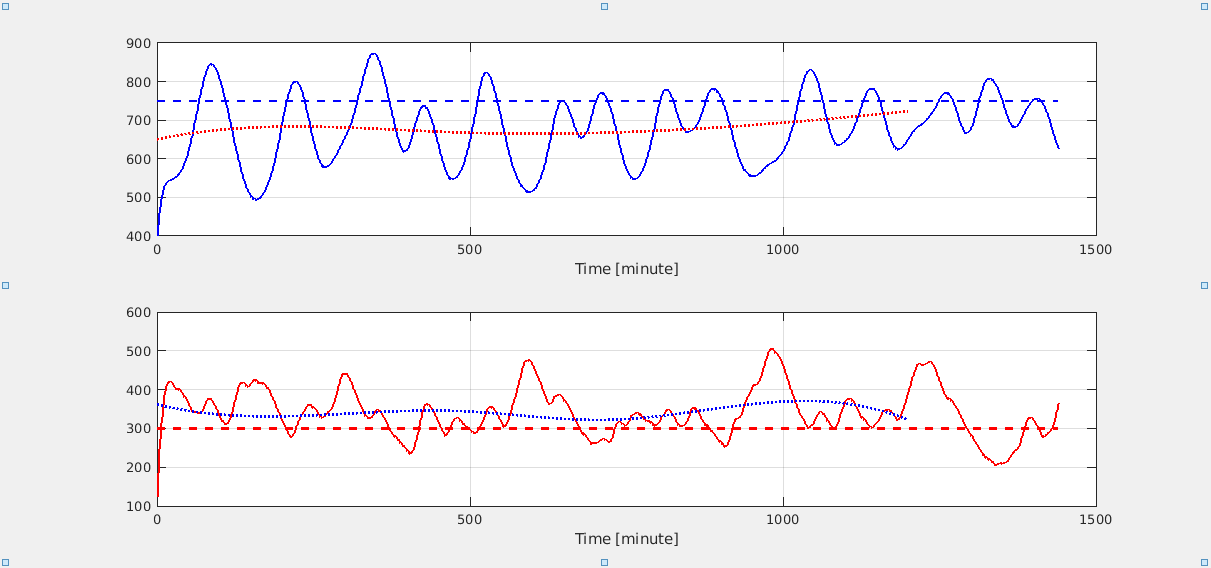

figure(3);
clf reset
plotbrowser('on');
title('Proteins');

subplot(2, 1, 1);
pl = plot(sim.Time, sim.Data(:,3), 'DisplayName','LacI');
set(pl,'linewidth',2, 'Color', 'b');
hold on
pl = plot(sim.Time, LacI_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', '--');
pl = plot(avg_time, avg_LacI, 'DisplayName','Average LacI');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

subplot(2, 1, 2);
pl = plot(sim.Time, sim.Data(:,5), 'DisplayName','TetR');
set(pl,'linewidth',2, 'Color', 'r');
hold on
pl = plot(sim.Time, TetR_ref*ones(1, length(sim.Time)), 'DisplayName','TetR Reference');
set(pl,'linewidth',2, 'Color', 'r', 'LineStyle', '--');
pl = plot(avg_time, avg_TetR, 'DisplayName','Average TetR');
set(pl,'linewidth',2, 'Color', 'b', 'LineStyle', ':');
xlabel('Time [minute]');
hold off
grid

[ISE,ITAE] = compute_performance_metrics(avg_LacI, avg_TetR, LacI_ref, TetR_ref)

ISE = 37.2801

ITAE = 1.2905e+05